ft = fittype('a*x^b', 'dependent', 'y', 'independent', 'x', 'coefficients', {'a' 'b'});
expFit = fit(xS, HS, ft, 'StartPoint', [0.4, 0.5])

expFit =      General model:
     expFit(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =      0.2847  (0.2743, 0.2952)
       b =      0.4774  (0.4442, 0.5107)


coef = coeffvalues(expFit);
HApp = coef(1).*x.^(coef(2));

Fit = fit(xB, HB, ft, 'StartPoint', [0.4, 0.5])

Fit =      General model:
     Fit(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =      0.3243  (0.3111, 0.3375)
       b =      0.3594  (0.3428, 0.3759)

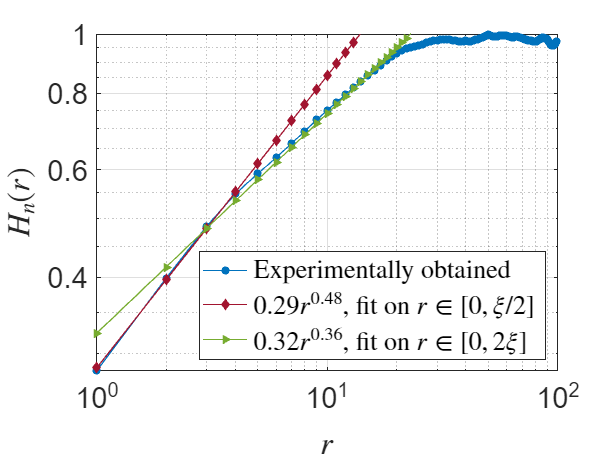

coef = coeffvalues(Fit);
HL = coef(1).*x.^(coef(2));

loglog(x, H, '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD"), hold on, grid on
loglog(x, HApp, '-d', 'MarkerSize',5, 'MarkerFaceColor', "#A2142F", 'MarkerEdgeColor', "#A2142F", 'Color',"#A2142F")
plot(x, HL, '->', 'MarkerSize',5, 'MarkerFaceColor', "#77AC30", 'MarkerEdgeColor', "#77AC30", 'Color', "#77AC30")
% xlim([0, 10])
ylim([0, 1])

ylabel('$$H_n(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')

legend('Experimentally obtained','$0.29r^{0.48}$, fit on $r \in [0, \xi/2]$', ...
    '$0.32r^{0.36}$, fit on $r \in [0, 2\xi]$', "Location", 'southeast', 'Interpreter','latex')

set(gca, 'FontSize', 20), hold off

% saveas(gcf, 'HurstFit.png')
